## **Exercício 5**

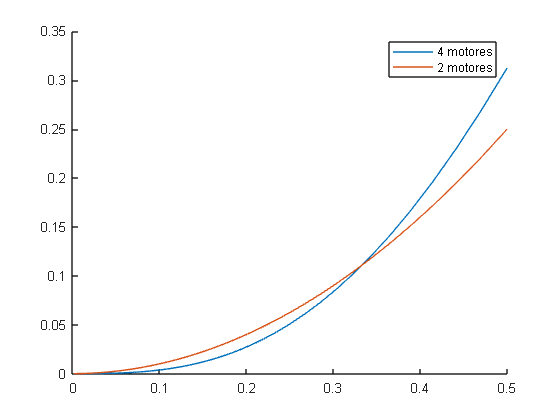

% X = Número de motores que falham
% Podemos considerar que X é uma variável binomial onde temos sucesso caso o motor falhe, e insucesso caso não falhe
% Como X á uma variável Binomial: %pX(k) = nCk * p^k * (1-p)^(n-k) = n! / (k! * (n-k)!) * p^k * (1-p)^(n-k)

% Vamos calcular a probabilidade de cair um avião com 2 motores, repetir a experiência para o de 4 motores, e comparar os resultados
% Avião de 2 motores -> despenha-se quando ambos os motores falharem (>50% dos motores falharem):

n = 2;
k = 2;
p = logspace(-3, log10(1/2),100);
p2Motores = factorial(n)/(factorial(k) * factorial(n-k)) .* p.^k .* (1-p).^(n-k);

% Avião de 4 motores -> despenha-se se 3 ou 4 motores falharem
p4Motores = 0;
n = 4;

k = 3;
p4Motores = p4Motores + factorial(n)/(factorial(k) * factorial(n-k)) .* p.^k .* (1-p).^(n-k);
k = 4;
p4Motores = p4Motores + factorial(n)/(factorial(k) * factorial(n-k)) .* p.^k .* (1-p).^(n-k);

figure(1);
hold on;

x = logspace(-3, log10(1/2),100);
plot(x,p4Motores);
plot(x,p2Motores);

legend("4 motores","2 motores");
hold off;